Preprocessing

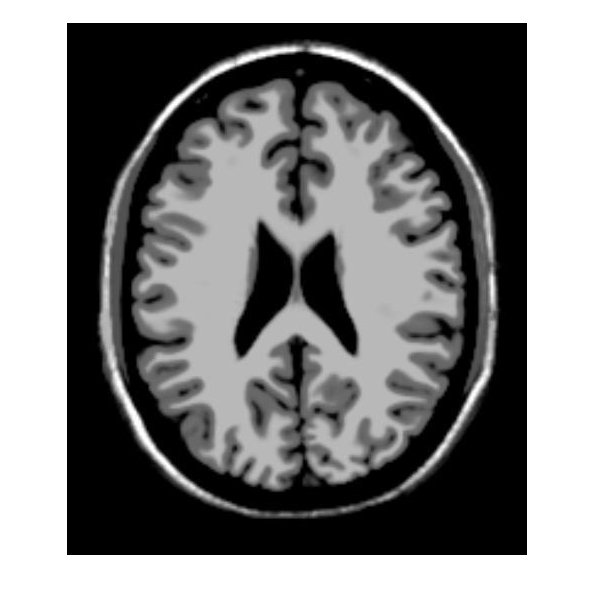

J1 = imread("T1.jpg");
imshow(J1)

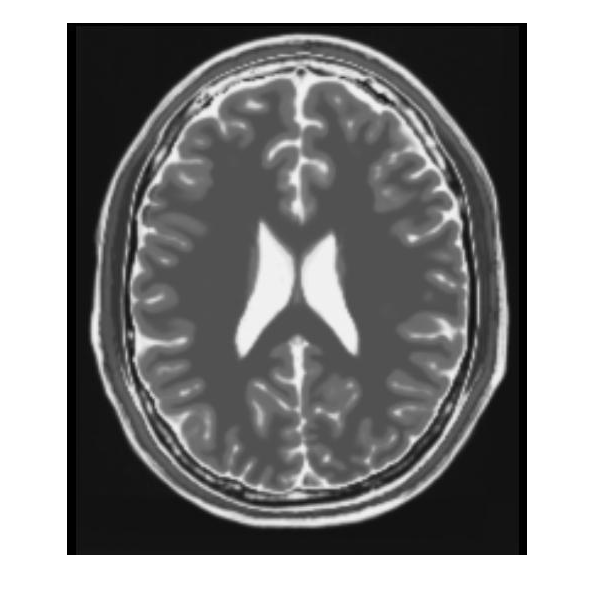

J1=J1+1;
J1 = double(J1);

J2 = imread("T2.jpg");
imshow(J2)

J2=J2+1

J2 = 532×460 uint8 matrix
    1    1    1    1    2    1    1    1    2    6    1    1    3    1    1    5    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1
    1    1    2    3    4    3    2    1    1    3    1    1    2    1    1    2    3    3    3    3    3    3    3    3    3    3    3    3    3    3    3    3    3    3    3    3    3    3    3    3    1    1    1    1    1    1    1    1    1    1
    1    3    4    6    6    5    4    4    1    7    6    4    8    5    1    5    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    6    6    6    6    6    6    6    6    6    6
    2    3    5    6    6    6    5    4    4   17   19   16   20   17   12   15   17   17   17   17   17   17   17   17   17   17   17   17   17   17   17   17   17   17   17   17   17   17   17   17   17   17   17   17 

a)

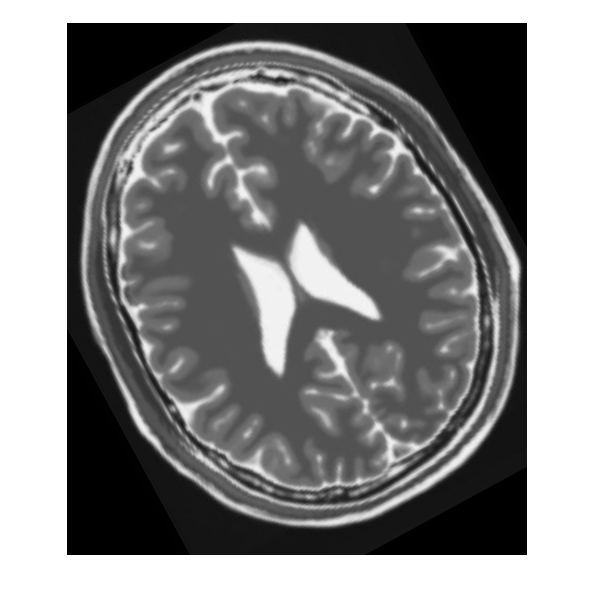

J3 = imrotate(J2,28.5,'bilinear','crop');
imshow(J3)

J3 = double(J3);

b)

NCC

nccs = zeros(1,91);
for s = 1:91
    J4 = imrotate(J3,s-46,'bilinear','crop');
    nccs(1,s) = ncc(J1,J4);
end

JE

jnts = zeros(1,91);
for s = 1:91
    J4 = imrotate(J3,s-46,'bilinear','crop');
    jnts(1,s) = JE3(J1,J4);
end

QMI

qmis = zeros(1,91);
for s = 1:91
    J4 = imrotate(J3,s-46,'bilinear','crop');
    qmis(1,s) = QMI(J1,J4);
end

c)

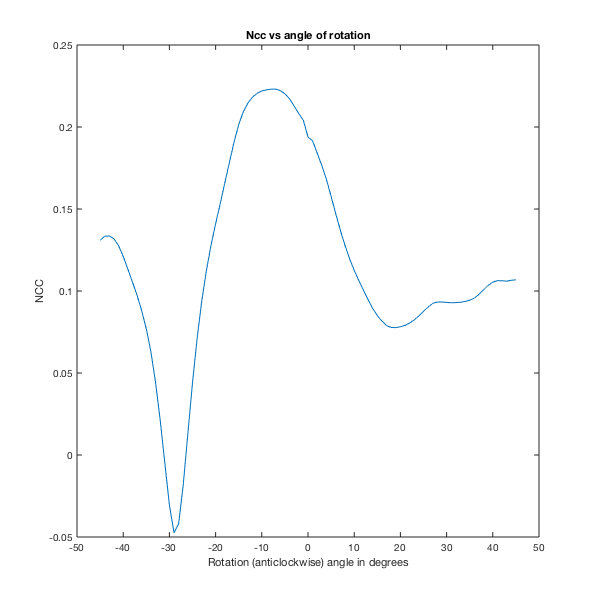

x = -45:45;
plot(x,nccs)
title("Ncc vs angle of rotation")
ylabel("NCC")
xlabel("Rotation (anticlockwise) angle in degrees")

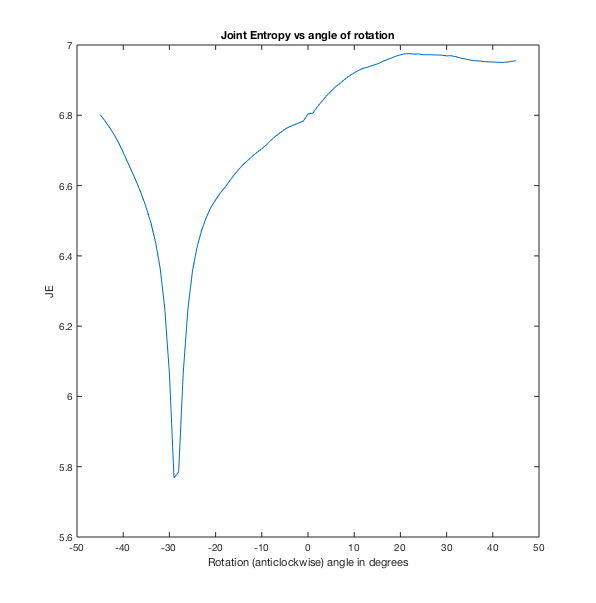

% 
plot(x,jnts)
ylabel("JE")
title("Joint Entropy vs angle of rotation")
xlabel("Rotation (anticlockwise) angle in degrees")

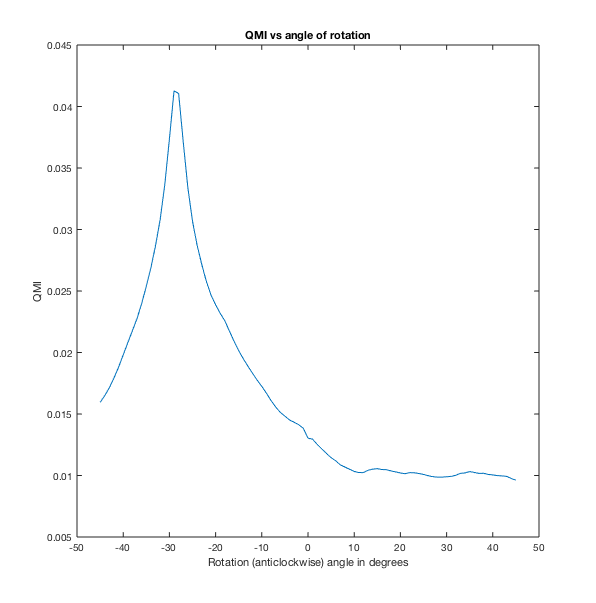

% 
plot(x,qmis)
ylabel("QMI")
title("QMI vs angle of rotation")
xlabel("Rotation (anticlockwise) angle in degrees")

d)

%using NCC
[M1, I1] = min(nccs);
disp("optimal value using NCC in degree anticlockwise is")

optimal value using NCC in degree anticlockwise is


disp(I1-46 )

   -29




[M2, I2] = min(jnts);
disp("optimal value using JE in degree anticlockwise is")

optimal value using JE in degree anticlockwise is


disp(I2-46 )

   -29




[M3, I3] = max(qmis);
disp("optimal value using QMI in degree anticlockwise is")

optimal value using QMI in degree anticlockwise is


disp(I3-46 )

   -29



e)

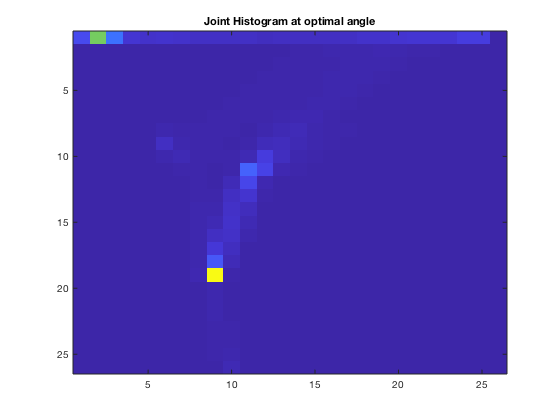

J4 = imrotate(J3,I2-46,'bilinear','crop');
jh = jointhist(J1,J4);
figure,imagesc(jh); colormap("default");
title("Joint Histogram at optimal angle")

Taking mean of only those pixels where I2 value is not 0

Similiarly taking only those values in calculation where I2 value is non zero

function value =  ncc(I1,I2)

    % First we will calculate the mean taking only those pixels which do
    % not have intensity =0 in Image I2 (rotated image) (the ones which are in field of view)
    totalI1 = 0;
    totalI2 = 0;
    [l,w] = size(I2);
    div=0;
    for i=1:l
        for j=1:w
            if I2(i,j) ==0
                continue
            else
                totalI1 = totalI1+I1(i,j);
                totalI2 = totalI2+I2(i,j);
                div=div+1;
            end
        end
    end
    
    meanI1 = totalI1/div;
    meanI2 = totalI2/div;
    
    % Now we would individually add the value corresponding to each
    % digitally corresponding pixels which are in field of view
    
    num=0;
    den1=0;
    den2 = 0;
    
    for i=1:l
        for j=1:w
            if I2(i,j) ==0
                continue
            else
                num= num +(I1(i,j) - meanI1)*(I2(i,j)-meanI2);
                den1= den1 +(I1(i,j) - meanI1)*(I1(i,j)-meanI1);
                den2= den2 +(I2(i,j) - meanI2)*(I2(i,j)-meanI2);
            end
        end
    end
    value = num/sqrt(den1*den2);
   end

% function jointent =  JE(I1,I2)
%    his1 = normhist(I1);
%    his2 = normhist(I2);
%    jointent = 0;
%    for h2 = 1:length(his2)
%         jointent = jointent-sum(his1*his2(h2).*log2(his1*his2(h2)));
%    end
% end


function jointent =  JE2(I1,I2)
   his1 = normhist(I1);
   his2 = normhist(I2);
   jointent = -sum(sum((transpose(his1)*his2).*log2(transpose(his1)*his2)));
end

function jointent =  JE3(I1,I2)
   jointhis = jointhist(I1,I2);
   total = sum(sum(jointhis));
   jointhis = jointhis/total;
   jointent = 0;
   for h1 = 1:26
       for h2 = 1:26
            if jointhis(h1,h2) == 0  %ignoring the ones which have 0 value
                continue
            else
                jointent = jointent-jointhis(h1,h2)*log2(jointhis(h1,h2));
            end    
       end
   end
end

function information =  QMI(I1,I2)
   jointhis = jointhist(I1,I2);
   total = sum(sum(jointhis));
   jointhis = jointhis/total;
   his1 = sum(jointhis,2);
   his2 = sum(jointhis,1);
   information = sum(sum((jointhis - his1*his2).*(jointhis - his1*his2)));
end


function arr = normhist(I1)
    h = size(I1);
    HW = h(1)*h(2);
    arr = zeros(1,26);
    for l = 1:26
        if l ==1
            arr(l) = sum(sum(I1 < l*10))/HW;
        else
            arr(l) = (sum(sum(I1 < l*10))-arr(l-1))/HW;
        end
    end
end

Taking bins from [1,11),[11,21) .......[251,256) 

In this way we will ignore all values which are outside the firld of view ( value of I2 at those pixels  is 0)

% This function would calculate jointhistogram considering only pixels
%which are in the desired field of view in I2 
%(basically the ones having greater than 0 intensity in I2 (rotated image)


function arr = jointhist(I1,I2)
    h = size(I1);
    HW = h(1)*h(2);
    arr = zeros(26,26);
    for i = 1:26
        for  j = 1:26
            arr(i,j) = sum(sum((I1 < i*10+1 & I1>= (i-1)*10+1) & (I2 < j*10+1 & I2>= (j-1)*10+1)));
        end
    end
end
